# Final Assignment 5SMB0

Kijk naar model validatie slides!! make een bode van parametric en non-parametric en vergelijk. zijn ze hetzelfde??? zo nee wat gaat er waar verkeerd. een dubbel check.

## Part 1: Understanding saturation and Butterworth filter

1.1 (3 points) The (partially) known parts of the system consist of F(q) and S. De termine by an initial experiment the parameter M and explain what influence F(q) and S will have on the identification of the unknown part H and G. This could be, e.g., on the remaining steps of the system identification cycle, limitations on the obtained final model, etc.

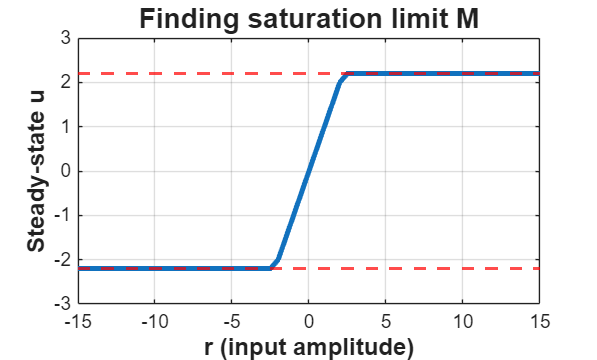

N = 500;
mode = 'open loop';

amplitudes = -15:0.5:15;
u_steady = zeros(size(amplitudes));

% loop over amplitudes and find steady state using the last 20 samples
for i = 1:length(amplitudes)
    r = amplitudes(i) * ones(N, 1);
    [u, f] = assignment_sys_14(r, mode);
    u_steady(i) = mean(u(end-20:end)); 
end
   
f = figure;

plot(amplitudes, u_steady, '-', 'LineWidth', 2.5);
hold on;

yline(2.2, '--r', 'LineWidth', 1.5);
yline(-2.2, '--r', 'LineWidth', 1.5);

xlabel('r (input amplitude)', 'FontSize', 12, 'FontWeight', 'bold'); 
ylabel('Steady-state u', 'FontSize', 12, 'FontWeight', 'bold');
title('Finding saturation limit M', 'FontSize', 14, 'FontWeight', 'bold');

grid on;

When looking at the graph we can duduce that the parameter M saturates at a steady state input above 2.2

## Part 2: Nonparametric identification

2.1 (4 points) We first want to get a rough idea of the frequency behavior of G0(q). To this end, we want to perform a preliminary experiment and apply nonparametric system identification using the collected data. The task is then to design an experiment of length N =1500. What type of reference shall be used? Give an expression of r(k) and motivate your choice.

Transient Detection

%clear; clc; close all;
% inspiration from A2_MultisineDesign.mlx
fs = 1; % Hz
N = 1500; % Number of samples
P = 5; % P > 2, see slides lecture 3
Np = N / P % sampeling period

Np = 300


Ts = 1/fs;  % sampling interval in seconds
f0 = fs/Np;  % the frequency resolution in Hz

fmin = 0.01; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = fs/2 -0.005;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2
% fmax = 0.35

t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

A = zeros(1,Np/2-1); 
A(bins+1)=1; % constant amplitude on the excited frequency bins, zero elsewhere

phi = zeros(1,Np/2-1); 
phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi

U = zeros(1, Np); 
U(bins+1) = A(bins+1) .* exp(1i*phi(bins+1)); 
r_period = real(ifft(U*Np)); % transform back to time domain

safe_amplitude = 2;
r_period = safe_amplitude * (r_period / max(abs(r_period))); 
r_period = r_period(:); 

r = repmat(r_period, P, 1);

mode = 'open loop';
[u, y] = assignment_sys_14(r, mode);

u_max = max(abs(u))

u_max = 1.6545

2.2 (4 points) Identify an FRF of the system. Motivate the chosen FRF estimator. What can we conclude from this FRF? Think of, e.g., high-frequency behavior, gain, res onance peaks, etc.

% put time domain data into matrices, each column is one period
u_matrix = reshape(u, Np, P);
y_matrix = reshape(y, Np, P);

% throw away first 2 periods to prevent leakage
u_ss = u_matrix(:, 3:end);
y_ss = y_matrix(:, 3:end);

% number of steady state periods
P_ss = P - 1;

% transform steady state to frequency domain
U_freq = fft(u_ss);
Y_freq = fft(y_ss);

% Maximum likelyhood FRF estimator => mean of output / mean of input
U_mean = mean(U_freq, 2);
Y_mean = mean(Y_freq, 2);

G_FRF = Y_mean ./ U_mean

G_FRF = 1.0e+12 *

   2.9299 + 0.0000i
  -1.2844 - 0.4593i
   1.2563 - 1.6731i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i


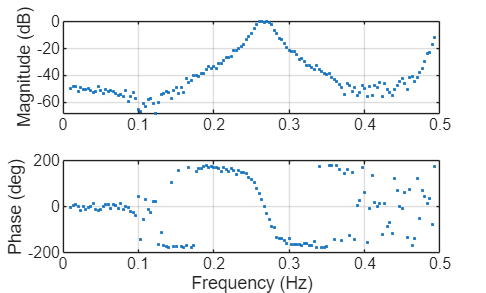


% make freq axis
freqs_hz = (0:Np-1)' * f0;
Nyquist_idx = floor(Np/2);

% only use excited frequencies
excited_indices = bins + 1;

% extract only the meaningful data
freqs_excited = freqs_hz(excited_indices);
G_FRF_excited = G_FRF(excited_indices);

% calculate Magnitude in dB
G_magnitude_dB = 20 * log10(abs(G_FRF_excited));
G_phase_deg = (angle(G_FRF_excited)) * (180/pi);

figure()
subplot(2,1,1);
plot(freqs_excited, G_magnitude_dB, '.', 'LineWidth', 4, 'MarkerSize', 4);
ylabel('Magnitude (dB)');
xlim([0, 0.5]); grid on;

subplot(2,1,2);
plot(freqs_excited, G_phase_deg, '.', 'LineWidth', 4, 'MarkerSize', 4);
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
xlim([0, 0.5]); grid on;

2.3 (4 points) Use the data generated in Part 2.1 to obtain an estimation of the non parametric noise model, i.e., derive an expression for estimating the noise spectrum Φv and plot the magnitude of the estimated noise power spectrum. What can you conclude from the estimated spectrum?

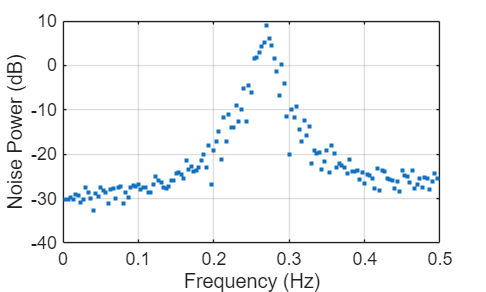

% calculate sample variance
Phi_v = var(Y_freq, 0, 2);

% power is mag^2 so use 10*log10 :)
Phi_v_dB = 10 * log10(abs(Phi_v));

% plot als freq up to niquist excluding 0 Hz
plot_indices = 2:Nyquist_idx;

figure()
plot(freqs_hz(plot_indices), Phi_v_dB(plot_indices), '.', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); 
ylabel('Noise Power (dB)');
xlim([0, 0.5]);
grid on;

If we compare the Bode plot (G) and the power specrtum (H), they bot look very similair in magnitude behaivior. Both have a resonance peak at 0.27 Hz. This suggest that th noise has similair/ the same poles as the system G.

## Part 3: Parametric identification and validation

3.1 (4 points) Based on the findings of the nonparametric identification, we want to get a parametric model of G0(q). Design a new experiment of length N = 3000. Choose a signal type of r(k) and motivate your choice.

The plots from part 2 suggest that th noise has similair/ the same poles as the system G. This means that we deal with an ARX/ ARMAX model structure (see lecture 6 slide 8).

clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2;
Ts = 1/fs;  % sampling interval in seconds

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.15/fn, 0.35/fn]; % normalize with the niquist freq
[b, a] = butter(4, wn, 'bandpass'); % check if n is sufficient
r_filtered = filtfilt(b, a, r_white_noise); % filter

% scale r to avoid saturation (M = 2.2)
safe_amplitude = 2.1;
r = safe_amplitude * (r_filtered / max(abs(r_filtered))); 
% r = safe_amplitude * r_white_noise

mode = 'open loop';
[u, y] = assignment_sys_14(r, mode);

u_max = max(abs(u))

u_max = 2.0787

3.2 (8 points) Using the designed input from Part 3.1, perform parametric identification of the system that yields a consistent estimate of G0. Motivate the choices that you make for, e.g., the model structure, model orders, validation methods, etc. Finally, compare the obtained results with the results from Part 2.

data = iddata(y, u, Ts);

% split data in train and test set
x_train = data(1:1500);
x_test = data(1501:3000);

delay = delayest(x_train)

delay = 4


% tune these maybe
na = 4; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 4; % nc is the order of the polynomial C(q)
nk = 0; % nk is the input-output delay

opt = armaxOptions;
opt.Focus = 'simulation';

opt1 = arxOptions;
opt1.Focus = 'simulation';

% define systems
sys_arx = arx(x_train, [na, nb, nk], opt1)


sys_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                            
  A(z) = 1 + 0.4012 z^-1 + 1.874 z^-2 + 0.3695 z^-3 + 0.8486 z^-4                              
                                                                                               
  B(z) = 0.002906 + 0.00151 z^-1 - 0.01516 z^-2 + 0.003105 z^-3 - 0.003467 z^-4 + 0.003507 z^-5
                                                                                               
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nk=0
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using ARX on time domain data "x_train".
Fit to estimation data: 85.53% (simulation focus) 
FPE: 1.406e-05, MSE: 0.0008994                    
 


sys_armax = armax(x_train, [na, nb, nc, nk], opt)


sys_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                        
  A(z) = 1 + 0.3987 z^-1 + 1.834 z^-2 + 0.3595 z^-3 + 0.812 z^-4                                 
                                                                                                 
  B(z) = 0.009939 + 0.002335 z^-1 + 0.003277 z^-2 + 0.002986 z^-3 + 0.01089 z^-4 + 0.0009354 z^-5
                                                                                                 
  C(z) = 1 + 0.0964 z^-1 - 0.00203 z^-2 - 0.08721 z^-3 - 0.04783 z^-4                            
                                                                                                 
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=6   nc=4   nk=0
   Number of free coefficients: 14
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using ARMAX on time domain da

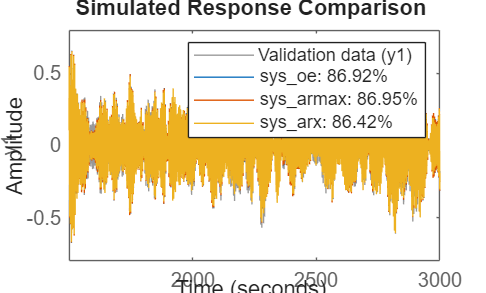

sys_oe = oe(x_train, [na, nb, nk]);

compare(x_test, sys_oe, sys_armax, sys_arx);

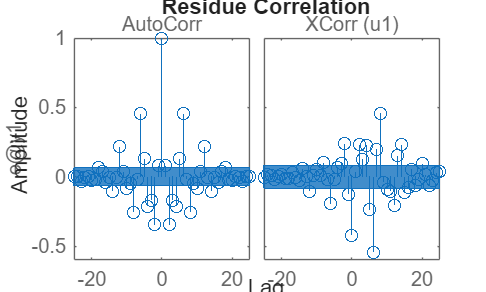


figure();
resid(x_test, sys_arx);

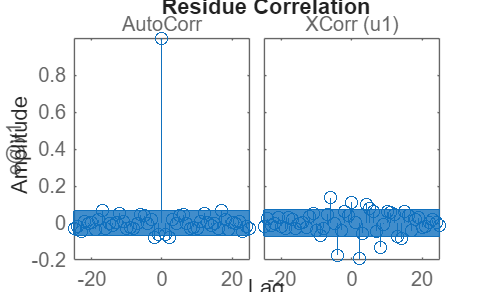


figure();
resid(x_test, sys_armax);

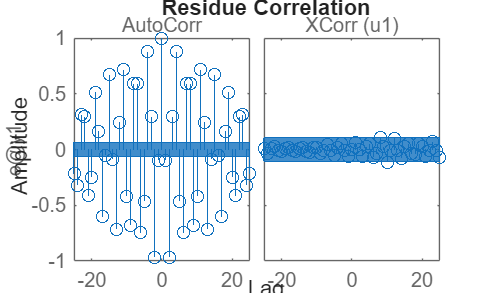


figure();
resid(x_test, sys_oe); % highly auto corr

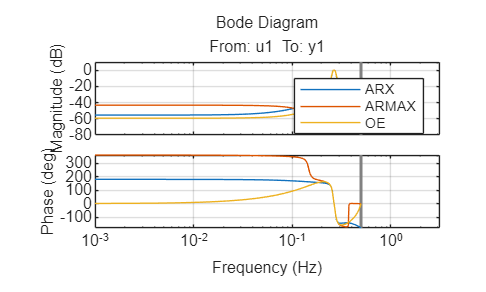


opts = bodeoptions;
opts.FreqUnits = 'Hz';

figure();
bode(sys_arx, sys_armax, sys_oe, opts);
legend('ARX', 'ARMAX', 'OE');
grid on;

tf(sys_armax ...
    )


ans =
 
  From input "u1" to output "y1":
  0.009939 + 0.002335 z^-1 + 0.003277 z^-2 + 0.002986 z^-3 + 0.01089 z^-4 + 0.0009354 z^-5
  ----------------------------------------------------------------------------------------
                  1 + 0.3987 z^-1 + 1.834 z^-2 + 0.3595 z^-3 + 0.812 z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.


## Part 4: Experimental verification of variance estimates

4.1 (4 points) We would like to get an understanding of the mechanism behind the estimation of the variance of identified parameters. To this end, we are going to introduce experiment repetition as a way to estimate the variance of an estimated model. We do this by performing Monte Carlo simulations, that is, repeating Question 3 for 100 times. Inspect the parameters obtained from the Monte Carlo simulations. Do we always get similar results from the different simulation runs? If not, could you explain why?

clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2;
Ts = 1/fs;  % sampling interval in seconds
runs = 100 % monte carlo iterations

runs = 100


na = 4; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 4; % nc is the order of the polynomial C(q)
nk = 0; % nk is the input-output delay

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.01/fn, 0.45/fn]; % normalize with the niquist freq
[b, a] = butter(6, wn, 'bandpass'); % check if n is sufficient
r_filtered = filtfilt(b, a, r_white_noise); % filter

% scale r to avoid saturation (M = 2.2)
safe_amplitude = 1.5;
r = safe_amplitude * (r_filtered / max(abs(r_filtered))); 

mode = 'open loop';

sys_all = cell(1, runs);

for i = 1:runs
    [u, y] = assignment_sys_14(r, mode);
    data = iddata(y, u, Ts);

    sys_mc = armax(data, [na, nb, nc, nk]);
    sys_all{i} = sys_mc;  
    
    A_params(i, :) = sys_mc.A(2:end); % remove the 1 (lecture 5/6)
    B_params(i, :) = sys_mc.B((end - nb + 1):end); % grab last 6 parameters ignore delay 0 

    if mod(i, 10) == 0
        disp("Iteration: " + i + "/ 100")
    end
end

Iteration: 10/ 100
Iteration: 20/ 100
Iteration: 30/ 100
Iteration: 40/ 100
Iteration: 50/ 100
Iteration: 60/ 100
Iteration: 70/ 100
Iteration: 80/ 100
Iteration: 90/ 100
Iteration: 100/ 100


cov_matrix = getcov(sys_mc);
var_A = diag(cov_matrix(1:na,1:na))';
var_B = diag(cov_matrix(na+1:na+nb,na+1:na+nb))';

sim_var_A = var(A_params, 0, 1);
sim_var_B = var(B_params, 0, 1);

error_A_abs = abs(sim_var_A - var_A);
error_A_rel = (error_A_abs ./ var_A) * 100;

error_B_abs = abs(sim_var_B - var_B);
error_B_rel = (error_B_abs ./ var_B) * 100;

% Display in console to easily copy to your Typst table
disp('--- Variance Comparison A(q) ---');

--- Variance Comparison A(q) ---


disp('Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)');

Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)


for i = 1:na
    fprintf('a_%d       | %1.4e      | %1.4e       | %2.2f%%\n', i, var_A(i), sim_var_A(i), error_A_rel(i));
end

a_1       | 2.0456e-05      | 2.1004e-05       | 2.68%
a_2       | 1.7349e-05      | 1.5968e-05       | 7.96%
a_3       | 2.2034e-05      | 2.3531e-05       | 6.79%
a_4       | 1.5237e-05      | 1.3490e-05       | 11.47%



disp('--- Variance Comparison B(q) ---');

--- Variance Comparison B(q) ---


disp('Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)');

Parameter | Theoretical Var | Monte Carlo Var | Relative Error (%)


for i = 1:nb
    fprintf('b_%d       | %1.4e      | %1.4e       | %2.2f%%\n', i, var_B(i), sim_var_B(i), error_B_rel(i));
end

b_1       | 1.4297e-08      | 1.5551e-08       | 8.77%
b_2       | 1.6643e-08      | 1.7518e-08       | 5.26%
b_3       | 1.5874e-08      | 1.6065e-08       | 1.20%
b_4       | 1.6906e-08      | 1.4980e-08       | 11.39%
b_5       | 1.7703e-08      | 1.2785e-08       | 27.78%
b_6       | 2.0355e-08      | 1.6227e-08       | 20.28%




w = logspace(-3, log10(0.5), 300)';

mag_all = zeros(length(w), runs);
phase_all = zeros(length(w), runs);

for i = 1:runs
    [mag, phase, ~] = bode(sys_all{i}, 2*pi*w);
    mag_all(:, i) = 20*log10(squeeze(mag));
    phase_all(:, i) = squeeze(phase);
    
    if mod(i, 10) == 0
        disp("Bode: " + i + "/100")
    end
end

Bode: 10/100
Bode: 20/100
Bode: 30/100
Bode: 40/100
Bode: 50/100
Bode: 60/100
Bode: 70/100
Bode: 80/100
Bode: 90/100
Bode: 100/100


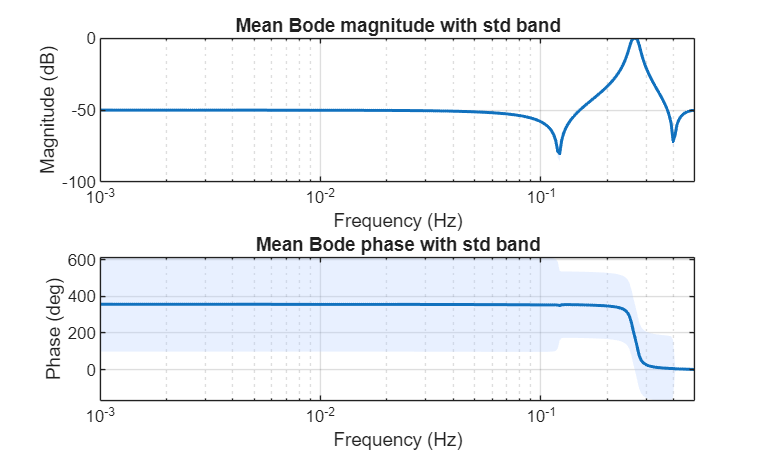


mag_mean = mean(mag_all, 2);
mag_std = std(mag_all, 0, 2);
phase_mean = mean(phase_all, 2);
phase_std = std(phase_all, 0, 2);

figure;

subplot(2,1,1)
upper = mag_mean + mag_std;
lower = mag_mean - mag_std;
fill([w; flipud(w)], [upper; flipud(lower)], [0.7 0.8 1], ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
plot(w, mag_mean, 'LineWidth', 1.5);
set(gca, 'XScale', 'log', 'XLim', [1e-3 0.5]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Mean Bode magnitude with std band');

subplot(2,1,2)
upper = phase_mean + phase_std;
lower = phase_mean - phase_std;
fill([w; flipud(w)], [upper; flipud(lower)], [0.7 0.8 1], ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
plot(w, phase_mean, 'LineWidth', 1.5);
set(gca, 'XScale', 'log', 'XLim', [1e-3 0.5]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
title('Mean Bode phase with std band');






% get cov of the last run
cov_matrix = getcov(sys_mc);
var_A = diag(cov_matrix(1:na, 1:na))';
var_B = diag(cov_matrix(na+1:na+nb, na+1:na+nb))';

% get var of the monte carlo sim
sim_var_A = var(A_params)

sim_var_A = 1.0e-04 *

    0.2100    0.1597    0.2353    0.1349


sim_var_B = var(B_params)

sim_var_B = 1.0e-07 *

    0.1555    0.1752    0.1606    0.1498    0.1279    0.1623


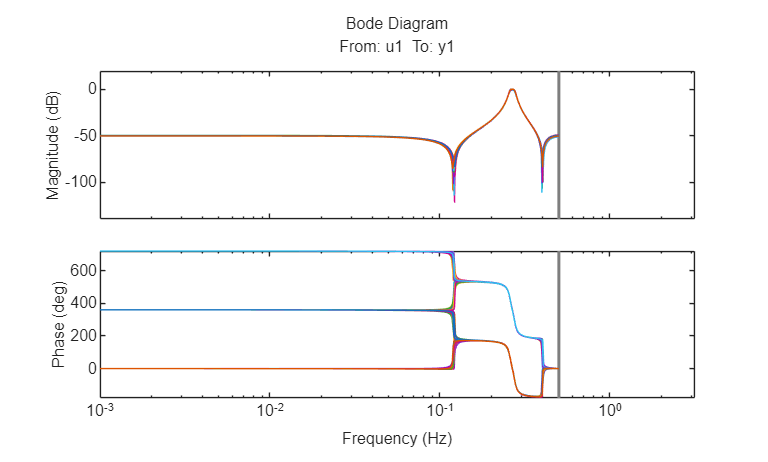

Bode: 10/ 100
Bode: 20/ 100
Bode: 30/ 100
Bode: 40/ 100
Bode: 50/ 100
Bode: 60/ 100
Bode: 70/ 100
Bode: 80/ 100
Bode: 90/ 100
Bode: 100/ 100



%%%% how to compare now??

opts = bodeoptions;
opts.FreqUnits = 'Hz';

figure();
hold on;
for i = 1:runs
    bode(sys_all{i}, opts);
    if mod(i, 10) == 0
        disp("Bode: " + i + "/ 100")
    end
end

## Part 5 MIMO

First FRF identification with schroeder 

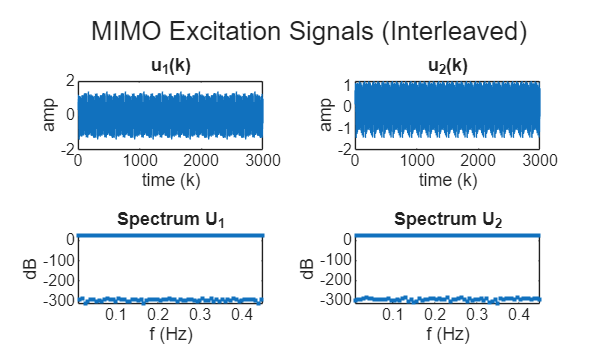

%% Part 2: Nonparametric Identification via Schroeder Multisine (now for MIMO)
% Setup parameters
N = 300;            % Samples per period
fs = 1.0;           % Sampling frequency (Hz)
Ts = 1/fs;
f0 = fs/N;          % Frequency resolution
N_per = 10;          % Number of periods

% Frequency Grid Design
fmin = 0.01; 
fmax = 0.45;        
nmin = ceil(fmin/f0);
nmax = floor(fmax/f0);
bins = nmin:nmax;   % Linear grid for Schroeder efficiency
F = length(bins);   % Number of excited frequencies

% For mimo give even bins to u1 and odd bins to u2 to keep them decoupled
bins_u1 = bins(1:2:end); % Odd bins
bins_u2 = bins(2:2:end); % Even bins

%% Setup Butterworth Filter F(q)
btt_num = [0.7157 1.4315 0.7157];
btt_den = [1 1.3490 0.5140];
Ts = 1.0; 
F_butter = tf(btt_num, btt_den, Ts);

% schroeder phase
% Formula: phi_k = -k*(k-1)*pi/F
k_idx = 0:F-1; 
phi_schroeder = -k_idx .* (k_idx + 1) * pi / F;

%% Rescale Amplitudes (Inverse Filter Gain)
% We counteract the Butterworth filter F(q) to keep excitation flat at the plant
w_bins = 2 * pi * (bins * f0); 
[mag, ~] = freqresp(F_butter, w_bins);
gain_array = max(squeeze(mag), 1e-4); % Avoid division by zero
A = 1 ./ gain_array; 

%% Construct Frequency Domain Signal
u1 = zeros(N, 1);
u2 = zeros(N, 1);

% Generate phases and spectra for u1
F1 = length(bins_u1);
k1 = 0:F1-1;
phi1 = -k1 .* (k1 + 1) * pi / F1;
A1 = A(1:2:end);
u1(bins_u1 + 1) = A1 .* exp(1j * phi1');

% Generate phases and spectra for u2
F2 = length(bins_u2);
k2 = 0:F2-1;
phi2 = -k2 .* (k2 + 1) * pi / F2;
A2 = A(2:2:end);
u2(bins_u2 + 1) = A2 .* exp(1j * phi2');

% Perform IFFT and ensure real signal
u1_p = real(ifft(u1)) * N;
u2_p = real(ifft(u2)) * N;

% Scale to maximize SNR without hitting the 2.2V saturation limit
total_max = max([abs(u1_p); abs(u2_p)]);
u1_scaled = 2.0 * (u1_p / total_max);
u2_scaled = 2.0 * (u2_p / total_max);

r_mimo = [repmat(u1_scaled, N_per, 1), repmat(u2_scaled, N_per, 1)];

mode = 'MIMO';
[u, y] = assignment_sys_14(r_mimo, mode);

% Discard the first period (transients) and average the rest
P_skip = 1;
u_matrix = reshape(u, N, N_per, 2);
y_matrix = reshape(y, N, N_per, 2);

u_avg = squeeze(mean(u_matrix(:, P_skip+1:end, :), 2));
y_avg = squeeze(mean(y_matrix(:, P_skip+1:end, :), 2));

U_fft = fft(u_avg);
Y_fft = fft(y_avg);

% Frequency Response Function (FRF)
G11 = Y_fft(bins_u1 + 1, 1) ./ U_fft(bins_u1 + 1, 1);
G21 = Y_fft(bins_u1 + 1, 2) ./ U_fft(bins_u1 + 1, 1);
G12 = Y_fft(bins_u2 + 1, 1) ./ U_fft(bins_u2 + 1, 2);
G22 = Y_fft(bins_u2 + 1, 2) ./ U_fft(bins_u2 + 1, 2);

f_vec = (0:N-1)*f0;
idx_plot = bins + 1; % Only plot where we actually excited the system

% Input response
figure; tcl1 = tiledlayout(2,2); title(tcl1, 'MIMO Excitation Signals (Interleaved)');
% Time domain
nexttile; plot(u(:,1)); xlabel('time (k)'); ylabel('amp'); title('u_1(k)');
nexttile; plot(u(:,2)); xlabel('time (k)'); ylabel('amp'); title('u_2(k)');
% Frequency domain (Averaged Spectra)
nexttile; plot(f_vec(1:end/2), db(abs(U_fft(1:end/2, 1))), '.'); 
xlabel('f (Hz)'); ylabel('dB'); title('Spectrum U_1'); xlim([fmin fmax]);
nexttile; plot(f_vec(1:end/2), db(abs(U_fft(1:end/2, 2))), '.'); 
xlabel('f (Hz)'); ylabel('dB'); title('Spectrum U_2'); xlim([fmin fmax]);

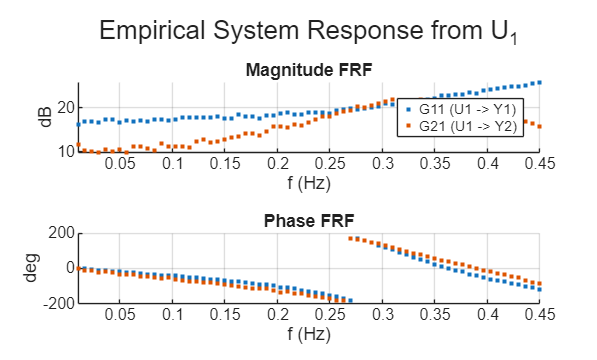


% u1 to Y
figure; tcl2 = tiledlayout(2,1); title(tcl2, 'Empirical System Response from U_1');
% Magnitude
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude FRF');
plot(bins_u1*f0, db(abs(G11)), '.', 'DisplayName', 'G11 (U1 -> Y1)');
plot(bins_u1*f0, db(abs(G21)), '.', 'DisplayName', 'G21 (U1 -> Y2)');
legend; xlim([fmin fmax]);
% Phase
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase FRF');
plot(bins_u1*f0, angle(G11)*180/pi, '.');
plot(bins_u1*f0, angle(G21)*180/pi, '.');
xlim([fmin fmax]);

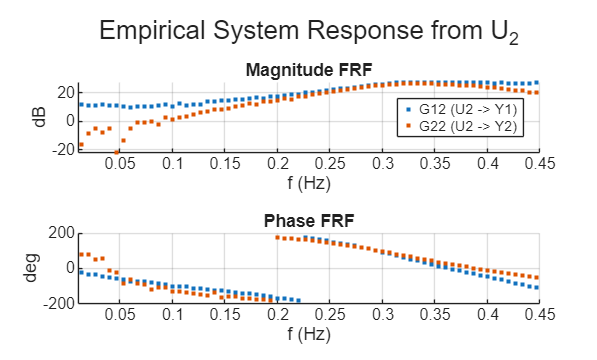


% u2 to Y
figure; tcl3 = tiledlayout(2,1); title(tcl3, 'Empirical System Response from U_2');
% Magnitude
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude FRF');
plot(bins_u2*f0, db(abs(G12)), '.', 'DisplayName', 'G12 (U2 -> Y1)');
plot(bins_u2*f0, db(abs(G22)), '.', 'DisplayName', 'G22 (U2 -> Y2)');
legend; xlim([fmin fmax]);
% Phase
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase FRF');
plot(bins_u2*f0, angle(G12)*180/pi, '.');
plot(bins_u2*f0, angle(G22)*180/pi, '.');
xlim([fmin fmax]);

### Parametric Modeling

N_mimo = 3000;
fs = 1.0;
Ts = 1/fs;

% Independent sequences so the inputs are uncorrelated
r1 = randn(N_mimo, 1);
r2 = randn(N_mimo, 1);

% Bandpass filter to stay within excitation limits 
wn = [0.01 0.45] / (fs/2);
[b_filt, a_filt] = butter(4, wn, 'bandpass');
r1_f = filtfilt(b_filt, a_filt, r1);
r2_f = filtfilt(b_filt, a_filt, r2);

% Scaling
r_mimo = 1.5 * [r1_f/max(abs(r1_f)), r2_f/max(abs(r2_f))];
max(r_mimo)

ans =     1.3876    1.5000


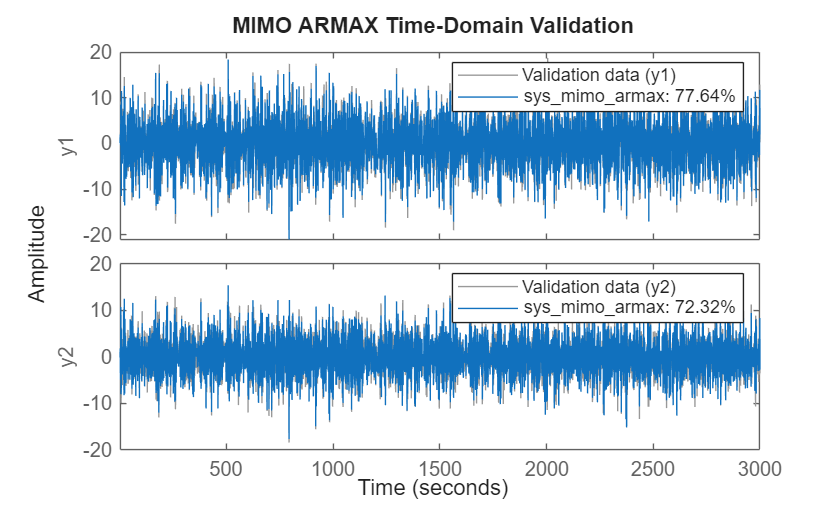


mode = 'MIMO';
[u_mimo, y_mimo] = assignment_sys_14(r_mimo, mode);
data_mimo = iddata(y_mimo, u_mimo, Ts);

% MIMO ARMAX Estimation
% na: Shared denominator order
% nb: 2x2 matrix for 2 inputs and 2 outputs
% nc: Noise model order
% nk: 2x2 matrix for input-output delays
na = [4 4; 
      4 4];
nb = [4 4;  % Numerator orders for [G11 G12]
      4 4]; % Numerator orders for [G21 G22]
nc = [4;
        4];
nk = [0 0;  % Delays for [G11 G12]
      0 0]; % Delays for [G21 G22]

opt = armaxOptions;
opt.Focus = 'simulation';
opt.EnforceStability = true;

sys_mimo_armax = armax(data_mimo, [na nb nc nk]);

figure;
compare(data_mimo, sys_mimo_armax);
title('MIMO ARMAX Time-Domain Validation');

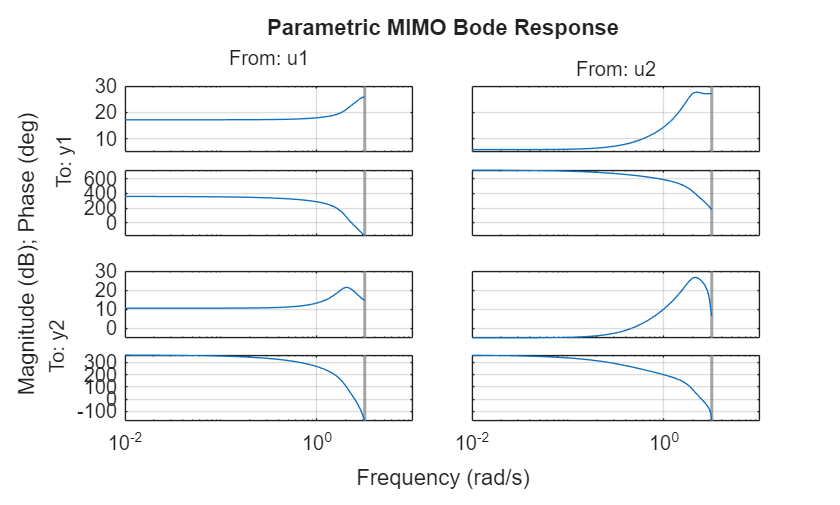


figure;
bode(sys_mimo_armax);
grid on;
title('Parametric MIMO Bode Response');

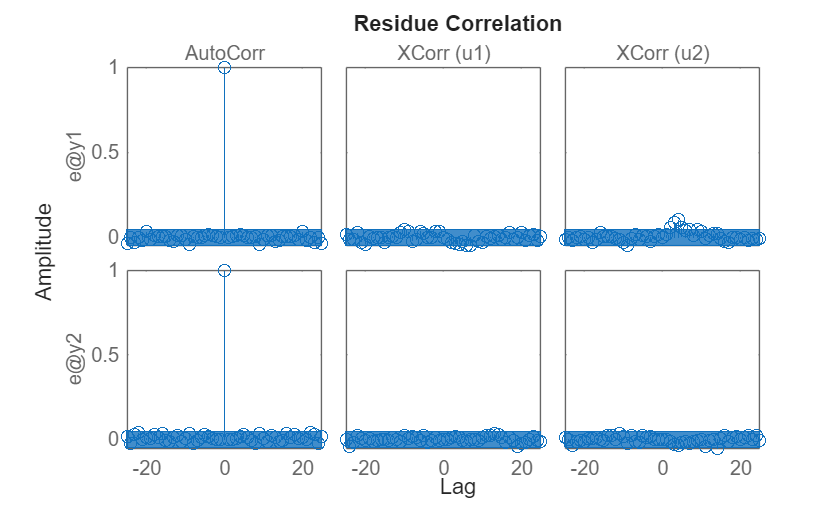


figure;
resid(data_mimo, sys_mimo_armax);

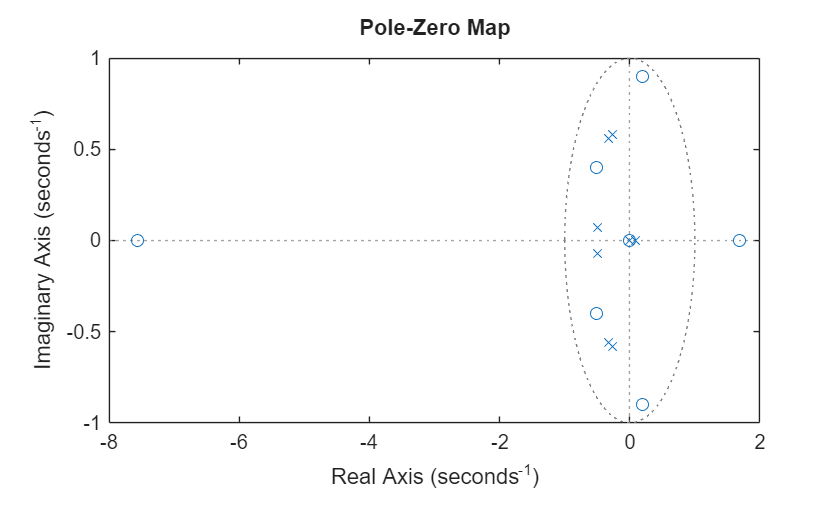


figure;
pzmap(sys_mimo_armax);

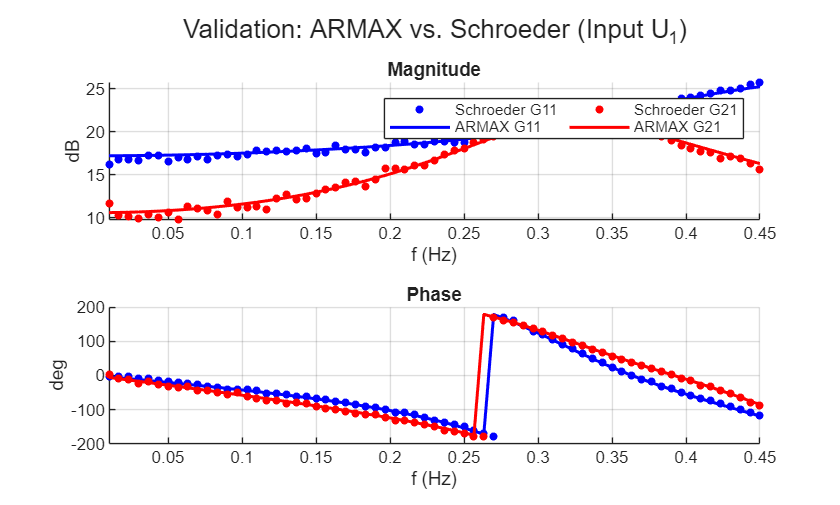

w_bins_u1 = 2 * pi * bins_u1 * f0; 
w_bins_u2 = 2 * pi * bins_u2 * f0;

H_armax_G11 = squeeze(freqresp(sys_mimo_armax(1,1), w_bins_u1)); 
H_armax_G21 = squeeze(freqresp(sys_mimo_armax(2,1), w_bins_u1)); 
H_armax_G12 = squeeze(freqresp(sys_mimo_armax(1,2), w_bins_u2)); 
H_armax_G22 = squeeze(freqresp(sys_mimo_armax(2,2), w_bins_u2)); 

figure; tcl_u1 = tiledlayout(2,1); title(tcl_u1, 'Validation: ARMAX vs. Schroeder (Input U_1)');

% Magnitude U1
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude');
plot(bins_u1*f0, db(abs(G11)), 'b.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G11');
plot(bins_u1*f0, db(abs(H_armax_G11)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'ARMAX G11');
plot(bins_u1*f0, db(abs(G21)), 'r.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G21');
plot(bins_u1*f0, db(abs(H_armax_G21)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'ARMAX G21');
legend('NumColumns', 2); xlim([fmin fmax]);

% Phase U1
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase');
plot(bins_u1*f0, angle(G11)*180/pi, 'b.', 'MarkerSize', 12);
plot(bins_u1*f0, angle(H_armax_G11)*180/pi, 'b-', 'LineWidth', 1.5);
plot(bins_u1*f0, angle(G21)*180/pi, 'r.', 'MarkerSize', 12);
plot(bins_u1*f0, angle(H_armax_G21)*180/pi, 'r-', 'LineWidth', 1.5);
xlim([fmin fmax]);

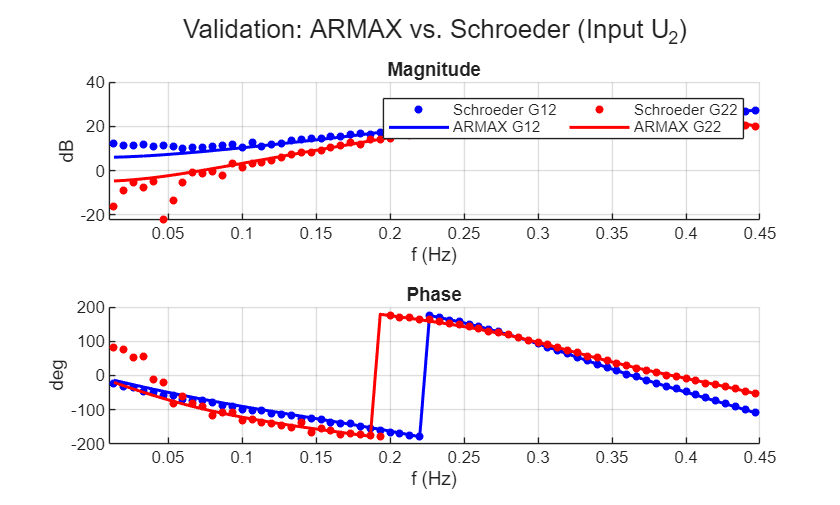


%%%%%

figure; tcl_u2 = tiledlayout(2,1); title(tcl_u2, 'Validation: ARMAX vs. Schroeder (Input U_2)');

% Magnitude U2
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('dB'); title('Magnitude');
plot(bins_u2*f0, db(abs(G12)), 'b.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G12');
plot(bins_u2*f0, db(abs(H_armax_G12)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'ARMAX G12');
plot(bins_u2*f0, db(abs(G22)), 'r.', 'MarkerSize', 12, 'DisplayName', 'Schroeder G22');
plot(bins_u2*f0, db(abs(H_armax_G22)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'ARMAX G22');
legend('NumColumns', 2); xlim([fmin fmax]);

% Phase U2
nexttile; hold on; grid on; xlabel('f (Hz)'); ylabel('deg'); title('Phase');
plot(bins_u2*f0, angle(G12)*180/pi, 'b.', 'MarkerSize', 12);
plot(bins_u2*f0, angle(H_armax_G12)*180/pi, 'b-', 'LineWidth', 1.5);
plot(bins_u2*f0, angle(G22)*180/pi, 'r.', 'MarkerSize', 12);
plot(bins_u2*f0, angle(H_armax_G22)*180/pi, 'r-', 'LineWidth', 1.5);
xlim([fmin fmax]);